warning off;
% clc
clear all

## ARQ parameters0

%Important parameters: L , Modulation, chanel coding , fft size, frmae size 
%L=2; %No of retransmsiion

Nbps=1; 
M=2^Nbps;       % Modulation order=2/4/6 for QPSK/16QAM/64QAM
EbN0=1:1:15;     % EbN0

%
N_iter=4000;     % no of packets   % Number of iterations for each EbN0
Nframe=1;       % no. of sybmols in on % Number of symbols per frame
sigPow=0;       % Signal power initialization
norms=[1 sqrt(2) 0 sqrt(10) 0 sqrt(42)];    % BPSK 4-QAM 16-QAM
%
NgType=1;       % NgType=1/2 for cyclic prefix/zero padding
if NgType==1, nt='CP';  elseif NgType==2, nt='ZP';   end

## Bob

PowerdB=[0 -8 -17 -21 -25]; % Channel tap power profile 'dB'
Delay=[0 3 5 6 8];          % Channel delay 'sample'
Power=10.^(PowerdB/10);     % Channel tap power profile 'linear scale'
Power=Power/(sum(Power));
Ntap=length(PowerdB);       % Chanel tap number
Lch=Delay(end)+1;           %Channel length

## Eve

PowerdBE=[0 -8 -17 -21 -25];
DelayE=[0 3 5 6 8];
PowerE=10.^(PowerdBE/10);       % Channel tap power profile 'linear scale'
NtapE=length(PowerdBE);         % Chanel tap number
LchE=DelayE(end)+1;             % Channel length(may be diff than no taps)

Nfft=64;                        % FFT size
Ng=16;                          % Ng=0: Guard interval length
Nsym=Nfft+Ng;                   % Symbol duration
Nvc=0;                          % Nvc=0: no virtual carrier
Nused=Nfft; 
 
for i=1:length(EbN0)

 BERu1=0;
 BERu2=0;
 BERu1E=0;
 BERu2E=0;
 
 bittot=0;
 symtot=0;
 
   for m=1:N_iter
      %h_ab  a=usr b=antena  r1 round 1
      %user1-atenna1 
 
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);%%%%%
       h11=zeros(1,Lch); 
       h11(Delay+1)=channel; % cir: channel impulse response
       h11r1=h11;
       H11r1=fft([h11r1 zeros(1,Nfft-Lch)]); % Channel frequency response
      %user2
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);%%%%%
       h21=zeros(1,Lch); 
       h21(Delay+1)=channel; % cir: channel impulse response
       h21r1=h21;
       H21r1=fft([h21r1 zeros(1,Nfft-Lch)]); % Channel frequency response
      
       %Eve
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);%%%%%
       hE1=zeros(1,Lch); 
       hE1(Delay+1)=channel; % cir: channel impulse response
       hEr1=hE1;
       HEr1=fft([hEr1 zeros(1,Nfft-Lch)]); % Channel frequency response
       
        %h_ab  a=usr b=antena
   
      %user1  
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);%%%%%
       h12=zeros(1,Lch); 
       h12(Delay+1)=channel; % cir: channel impulse response
       h12r2=h12;
       H12r2=fft([h12r2 zeros(1,Nfft-Lch)]); % Channel frequency response
      
       %user2
      % rng;
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);%%%%%
       h22=zeros(1,Lch); 
       h22(Delay+1)=channel; % cir: channel impulse response
       h22r2=h22;
       H22r2=fft([h22r2 zeros(1,Nfft-Lch)]); % Channel frequency response
     
       %Eve
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);%%%%%
       hE2=zeros(1,Lch); 
       hE2(Delay+1)=channel; % cir: channel impulse response
       hEr2=hE2;
       HEr2=fft([hEr2 zeros(1,Nfft-Lch)]); % Channel frequency response
       
       % User1 Tx______________________________________________________________
       
      X= randi([0,M-1], Nused*Nframe,1)'; % bit: integer vector
      Xmod= qammod(X,M,'gray')/norms(Nbps); %%
      if NgType~=2, x_GI=zeros(1,Nframe*Nsym);
      elseif NgType==2, x_GI= zeros(1,Nframe*Nsym+Ng);
        % Extend an OFDM symbol by Ng zeros 
      end
      
      % User2 Tx______________________________________________________________
    
      X2= randi([0,M-1], Nused*Nframe,1)'; % bit: integer vector
      %   X= randint(1,Nused*Nframe,M); % bit: integer vector %Non binary data 0 1 2 3
      Xmod2= qammod(X2,M,'gray')/norms(Nbps); %%
      if NgType~=2, x_GI2=zeros(1,Nframe*Nsym);
      elseif NgType==2, x_GI2= zeros(1,Nframe*Nsym+Ng);
        % Extend an OFDM symbol by Ng zeros 
      end

%%Modulted signal for user1 and user2      
      U1=Xmod;
      U2=Xmod2;
 
  %Precoding matrix 
  %h_ab  a=usr b=antena

 M_1a=diag(H22r2)*(diag(H22r2)*diag(H11r1)-diag(H21r1)*diag(H12r2))^-1;
 M_1b=-(M_1a*diag(H21r1))/diag(H22r2);

 M_2a=diag(H12r2)*(diag(H21r1)*diag(H12r2)-diag(H22r2)*diag(H11r1))^-1;
 M_2b=-(M_2a*diag(H11r1))/diag(H12r2);

## Normaization factore

Tx1=(1/sqrt(2))*U1*M_1a+(1/sqrt(2))*U2*M_2a;  
Tx2=(1/sqrt(2))*U1*M_1b+(1/sqrt(2))*U2*M_2b;

## PRecoded: This is imp

         x1= ifft(Tx1)/norm(ifft(Tx1),2);  %% This is how i am normalizign it :step1
        
         x_GI1= guard_interval(Ng,Nfft,NgType,x1);       
         y11= conv(x_GI1,h11r1); %RX1 TX1
         y21=(conv(x_GI1,h21r1)); %RX2 TX1
         yE1= conv(x_GI1,hEr1); %RXE TX1
         
         
        x2= ifft(Tx2)/norm(ifft(Tx2),2);
        x_GI2= guard_interval(Ng,Nfft,NgType,x2);       
        y12=conv(x_GI2,h12r2);  %RX1 TX2
        y22= conv(x_GI2,h22r2); %RX2 TX2
        yE2= conv(x_GI2,hEr2);  %RXE TX2   

       
       snr = EbN0(i)+10*log10(Nbps*(Nused/Nfft)); 
       
       %Noise 1
       EEs=sum(x1).^2/length(x1);    
       noise_mag  = sqrt(0.5*EEs*((10.^(-snr/10))));
       n1 =  noise_mag*(randn(size(y11))+1i*randn(size(y11)));

        %Noise 2
       EEs=sum(x2).^2/length(x2);    
       noise_mag = sqrt(0.5*EEs*((10.^(-snr/10))));    
       n2 = noise_mag*(randn(size(y12))+1i*randn(size(y12)));
       
       
       %===============================================
       Y1 = norm(ifft(Tx1),2)*y11 + norm(ifft(Tx2),2)*y12 + n1;
       Y1new = fft(remove_GI(Ng,Nsym,NgType,Y1));
       
       Y2 = norm(ifft(Tx1),2)*y21 + norm(ifft(Tx2),2)*y22 + n2;
       Y2new = fft(remove_GI(Ng,Nsym,NgType,Y2));

        UU1i=qamdemod(Y1new*norms(Nbps),M,'gray');
        UU2i=qamdemod(Y2new*norms(Nbps),M,'gray');
 

        symtot=symtot+Nfft;

        BERu1=BERu1+sum(sum(de2bi(UU1i,Nbps)~=de2bi(X,Nbps)));
        BERu2= BERu2+sum(sum(de2bi(UU2i,Nbps)~=de2bi(X2,Nbps)));

        bittot=bittot+Nfft*Nbps; 
   end
 
%BER
 BERu11(i)=BERu1/bittot;
 BERu21(i)=BERu2/bittot;


end

[EbN0,BER_sim] = BERofBPSKinAWGN();
[EbN0,ber]=BERofQPSKinAWGN();
[EbN0,simBer]=OFDMberINawgn();

[BERu11orig, BERu21orig] = WP3_NO_MRC(N_iter); % original
%

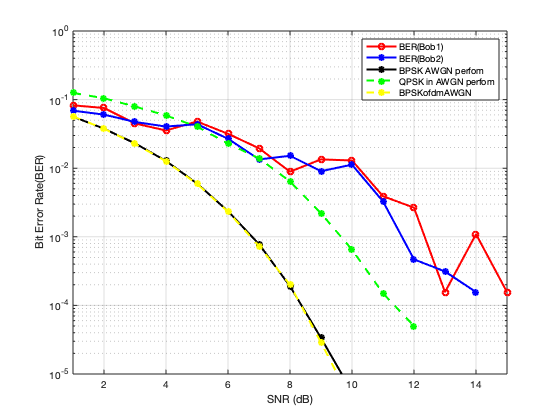

figure(1);
semilogy(EbN0,BERu11,'or-','LineWidth',2); hold on;
semilogy(EbN0,BERu21,'*b-','LineWidth',2);hold on;
semilogy(EbN0,BER_sim,'-k*','LineWidth',2);  hold on;
semilogy(EbN0,ber,'--g*','LineWidth',2);  hold on;
semilogy(EbN0,simBer,'--y*','LineWidth',2);  hold off;
axis([min(EbN0) max(EbN0) 10^(-5) 1]);
xlabel('SNR (dB)');
ylabel('Bit Error Rate(BER)');
legend('BER(Bob1)','BER(Bob2)', 'BPSK AWGN perfom','QPSK in AWGN perfom','BPSKofdmAWGN');
grid on;

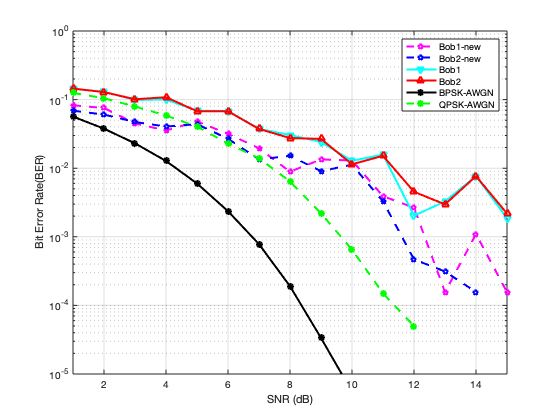

semilogy(EbN0,BERu11,'pm--','LineWidth',2); hold on;
semilogy(EbN0,BERu21,'pb--','LineWidth',2);hold on;
semilogy(EbN0,BERu11orig,'vc-','LineWidth',2); hold on;
semilogy(EbN0,BERu21orig,'^r-','LineWidth',2);  hold on;
semilogy(EbN0,BER_sim,'-k*','LineWidth',2);  hold on;
semilogy(EbN0,ber,'--g*','LineWidth',2);  hold on;
axis([min(EbN0) max(EbN0) 10^(-5) 1]);
xlabel('SNR (dB)');
ylabel('Bit Error Rate(BER)');
legend('Bob1-new','Bob2-new','Bob1','Bob2','BPSK-AWGN', 'QPSK-AWGN');
grid on;